% COMBINED DATASET: mitdb + qtdb + nstdb (all resampled to 10 Hz via Min‑Max)

clear; close all; clc;

warning('off', 'MATLAB:colon:operandsNotLogicalScalar');

% -------------------------------------------------------------------------
% List of databases
% -------------------------------------------------------------------------
database_list = {'qtdb','mitdb','nstdb'};

% -------------------------------------------------------------------------
% Global parame ters
% -------------------------------------------------------------------------
Fs_target = 10;                     % final detection frequency (Hz)
lowcut = 8; highcut = 25; filterOrder = 2;
tol_ms = 150;                       % matching tolerance (ms)
trim_start_s = 1;                   % seconds to trim from start

% -------------------------------------------------------------------------
% Pre‑process all records from all databases
% -------------------------------------------------------------------------
all_sparse = {};        % cell array of sparse signals (10 Hz)
all_sparse_idx = {};    % cell array of original sample indices for each sparse point
all_gt_native = {};     % ground truth indices in original native samples
all_Fs_orig = [];       % original sampling rate for each record
all_record_names = {};  % for debugging

for db = database_list
    dbname = db{1};
    fprintf('\n--- Processing database: %s ---\n', dbname);

    % Database‑specific settings
    switch dbname
        case 'mitdb'
            dataDir = 'mitdb-mat';
            cacheFile = 'allData_mitdb.mat';
            Fs_orig_native = 360;
            records = {'100','101','102','103','104','105','106','107','108','109', ...
                '111','112','113','114','115','116','117','118','119','121', ...
                '122','123','124','200','201','202','203','205','207','208', ...
                '209','210','212','213','214','215','217','219','220','221', ...
                '222','223','228','230','231','232','233','234'};

            divisor = 36;   % because 360/36 = 10
        case 'qtdb'
            dataDir = 'qtdb-mat';
            cacheFile = 'allData_qtdb.mat';
            Fs_orig_native = 250;
            records = {'sel30','sel31','sel32','sel33','sel34','sel35','sel36','sel37','sel38','sel39', ...
                'sel40','sel41','sel42','sel43','sel44','sel45','sel46','sel47','sel48','sel49', ...
                'sel50','sel51','sel52','sel100','sel102','sel103','sel104','sel114','sel116','sel117', ...
                'sel123','sel213','sel221','sel223','sel230','sel231','sel232','sel233','sel301','sel302', ...
                'sel306','sel307','sel308','sel310','sel803','sel808','sel811','sel820','sel821','sel840', ...
                'sel847','sel853','sel871','sel872','sel873','sel883','sel891','sel14046','sel14157','sel14172', ...
                'sel15814','sel16265','sel16272','sel16273','sel16420','sel16483','sel16539','sel16773','sel16786', ...
                'sel16795','sel17152','sel17453','sele0104','sele0106','sele0107','sele0110','sele0111','sele0112', ...
                'sele0114','sele0116','sele0121','sele0122','sele0124','sele0126','sele0129','sele0133','sele0136', ...
                'sele0166','sele0170','sele0203','sele0210','sele0211','sele0303','sele0405','sele0406','sele0409', ...
                'sele0411','sele0509','sele0603','sele0604','sele0606','sele0607','sele0609','sele0612','sele0704'};
            divisor = 25;   
        case 'nstdb'
            dataDir = 'nstdb-mat';
            cacheFile = 'allData_nstdb.mat';
            Fs_orig_native = 360;
            records = {'118e00','118e06','118e12','118e18','118e24','118e_6', ...
                '119e00','119e06','119e12','119e18','119e24','119e_6'};
            divisor = 36;
        otherwise
            error('Unknown database');
    end
    Fs_orig = Fs_orig_native;   % we keep original sampling rate

    % Load or rebuild cache for this database
    if exist(cacheFile, 'file')
        fprintf('Loading cached data from %s...\n', cacheFile);
        load(cacheFile, 'all_ecg', 'all_gt');
        % Ensure column vectors
        for i = 1:length(all_ecg)
            if size(all_ecg{i},2) > 1, all_ecg{i} = all_ecg{i}(:,1); end
            all_ecg{i} = all_ecg{i}(:);
        end
    else
        fprintf('Reading raw files and fixing annotations...\n');
        all_ecg = cell(length(records),1);
        all_gt  = cell(length(records),1);
        for i = 1:length(records)
            rec = records{i};
            sigFile = fullfile(dataDir, [rec, '.txt']);
            annFile = fullfile(dataDir, [rec, '-ann.txt']);
            all_ecg{i} = load(sigFile);
            all_ecg{i} = all_ecg{i}(:);
            ann_raw = load(annFile);
            if size(ann_raw,2) > 1
                all_gt{i} = round(ann_raw(:,1));
            else
                all_gt{i} = round(ann_raw(:));
            end
            if mod(i,30)==0, fprintf('Record %-10s : %5d beats\n', rec, length(all_gt{i})); end
        end
        save(cacheFile, 'all_ecg', 'all_gt');
        fprintf('Cache rebuilt.\n');
    end

    % Design bandpass filter (same for all records in this database)
    nyquist = Fs_orig / 2;
    [b_bp, a_bp] = butter(filterOrder, [lowcut, highcut]/nyquist, 'bandpass');

    % Pre‑compute sparse representation at 10 Hz for each record
    for i = 1:length(all_ecg)
        ecg_raw = all_ecg{i};
        % Bandpass filter
        ecg_filt = filtfilt(b_bp, a_bp, ecg_raw);

        % Min‑Max downsampling to exactly Fs_target (10 Hz)
        blockSize = round(2 * Fs_orig / Fs_target);   % = 2*divisor
        N = floor(length(ecg_filt)/blockSize) * blockSize;
        if N == 0
            warning('Record %s too short, skipping', records{i});
            continue;
        end
        blocks = reshape(ecg_filt(1:N), blockSize, []);
        [~, min_pos] = min(blocks, [], 1);
        [~, max_pos] = max(blocks, [], 1);
        min_idx = (0:size(blocks,2)-1)*blockSize + min_pos;
        max_idx = (0:size(blocks,2)-1)*blockSize + max_pos;
        sparse_idx_all = [min_idx, max_idx];
        sparse_val_all = [blocks(sub2ind(size(blocks), min_pos, 1:size(blocks,2))), ...
            blocks(sub2ind(size(blocks), max_pos, 1:size(blocks,2)))];
        [sparse_idx, sort_order] = sort(sparse_idx_all);
        sparse_val = sparse_val_all(sort_order);
        [sparse_idx, ia] = unique(sparse_idx, 'stable');
        sparse_val = sparse_val(ia);

        % Trim start (trim_start_s seconds at 10 Hz)
        trim_len = round(trim_start_s * Fs_target);
        if length(sparse_val) > trim_len
            sparse_idx = sparse_idx(trim_len+1:end);
            sparse_val = sparse_val(trim_len+1:end);
        else
            continue;
        end

        % Store
        all_sparse{end+1} = sparse_val;
        all_sparse_idx{end+1} = sparse_idx;
        all_gt_native{end+1} = all_gt{i};
        all_Fs_orig(end+1) = Fs_orig;
        all_record_names{end+1} = sprintf('%s_%s', dbname, records{i});
    end
end


--- Processing database: qtdb ---


Loading cached data from allData_qtdb.mat...



--- Processing database: mitdb ---


Loading cached data from allData_mitdb.mat...



--- Processing database: nstdb ---


Loading cached data from allData_nstdb.mat...



nRec_total = length(all_sparse);
fprintf('\nTotal records combined: %d\n', nRec_total);


Total records combined: 165




% -------------------------------------------------------------------------
% OPTIMIZATION OF DETECTOR PARAMETERS
% -------------------------------------------------------------------------
fprintf('\n========================================\n');

fprintf('OPTIMIZATION: Elgendi detector parameters (mixed-integer)\n');

OPTIMIZATION: Elgendi detector parameters (mixed-integer)


fprintf('Fixed filter: lowcut=%d Hz, highcut=%d Hz, order=%d\n', lowcut, highcut, filterOrder);

Fixed filter: lowcut=8 Hz, highcut=25 Hz, order=2


fprintf('Target detection frequency = %d Hz (Fs_target)\n', Fs_target);

Target detection frequency = 10 Hz (Fs_target)


fprintf('Combined database: mitdb + qtdb + nstdb (total %d records)\n', nRec_total);

Combined database: mitdb + qtdb + nstdb (total 165 records)


fprintf('========================================\n');

Scalar objective function
Number of variables: 11
Number of integer constraints: 5
Number of linear inequality constraints: 0
Number of linear equality constraints: 0
Number of nonlinear inequality constraints: 0

F-count       Time        Best          Current         Trial
             (seconds)    Fval          Fval            type
   1         2.81      -9.7839e-01     -9.7839e-01   random 
   2         3.01      -9.8535e-01     -9.8535e-01   random 
   3         3.05      -9.8535e-01     -9.6746e-01   random 
   4         3.10      -9.8535e-01     -9.7830e-01   random 
   5         3.14      -9.8535e-01     -9.7679e-01   random 
   6         3.19      -9.8535e-01     -9.8531e-01   random 
   7         3.23      -9.8535e-01     -9.7836e-01   random 
   8         3.29      -9.8535e-01     -9.8203e-01   random 
   9         3.33      -9.8535e-01     -8.5959e-01   random 
  10         4.12      -9.8535e-01     -7.3505e-01   random 
  11         4.31      -9.8535e-01     -4.7952e-01   

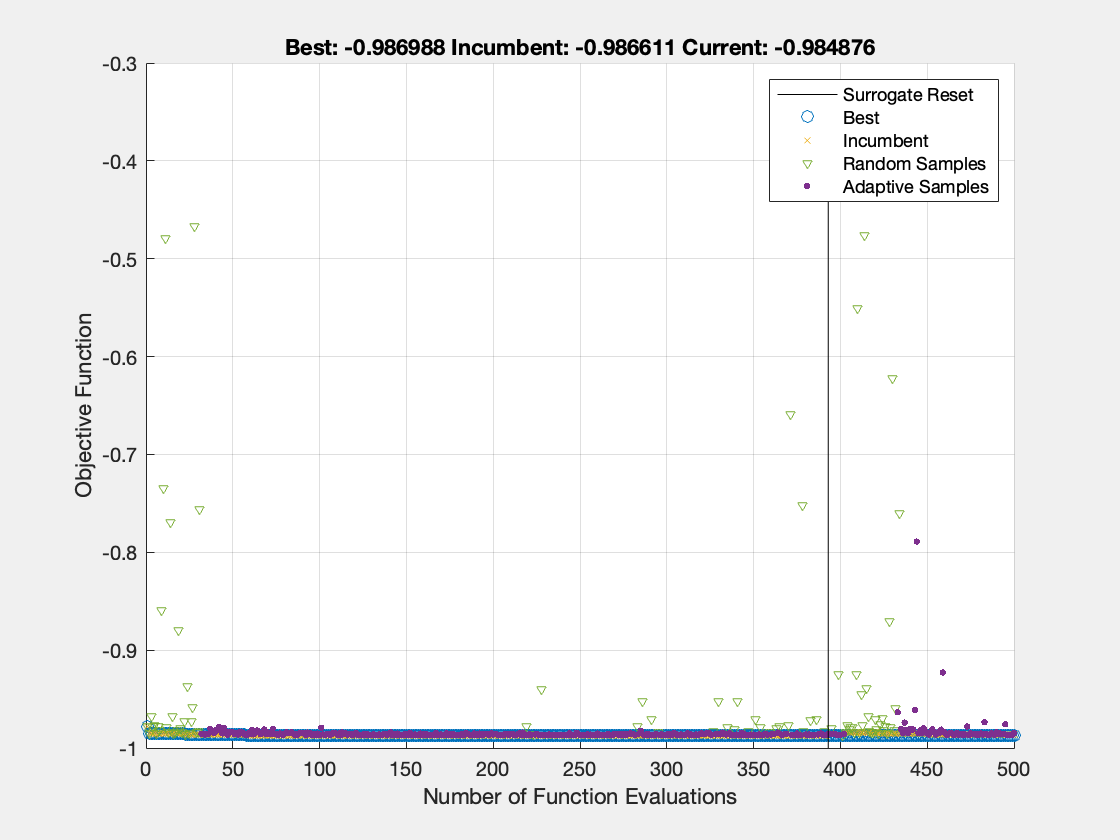


% Use all, or some
n_val_records = min(250, nRec_total);   % adjust as needed
val_idx = 1:n_val_records;

% Define objective function – uses pre‑computed sparse signals
obj_fun = @(params) objective_minus_f1_combined(params, all_sparse(val_idx), all_sparse_idx(val_idx), ...
    all_gt_native(val_idx), all_Fs_orig(val_idx), ...
    Fs_target, tol_ms);

% 11 variables
lb = [1,   2,   0.005, 0,   0,    0.01, 50, 5,   0.1,   0.5,   1.0];
ub = [8,   14,  0.2,   3,   1,    0.2,  99, 30,  0.6,   1.0,   2.0];
intcon = [1, 2, 4, 7, 8];   % wq, wb, ref, perc, win_len_sec (indices 1,2,4,7,8)


opts = optimoptions('surrogateopt', ...
    'PlotFcn', 'surrogateoptplot', ...
    'MaxFunctionEvaluations', 500, ...
    'UseParallel', true, ...
    'Display', 'iter');

tic_opt = tic;
best_params_vec = surrogateopt(obj_fun, lb, ub, intcon, opts);

opt_time = toc(tic_opt);

best_wq   = round(best_params_vec(1));
best_wb   = round(best_params_vec(2));
best_beta = best_params_vec(3);
best_ref  = round(best_params_vec(4));
best_alpha= best_params_vec(5);
best_hth  = best_params_vec(6);
best_perc      = round(best_params_vec(7));
best_win_len   = round(best_params_vec(8));
best_rr_tol    = best_params_vec(9);
best_low_factor= best_params_vec(10);
best_high_factor = best_params_vec(11);

fprintf('  wq=%d, wb=%d, beta=%.4f, ref=%d, alpha=%.3f, height=%.3f, perc=%d, win_len=%d\n', ...
    best_wq, best_wb, best_beta, best_ref, best_alpha, best_hth, best_perc, best_win_len);

  wq=4, wb=8, beta=0.0516, ref=0, alpha=0.372, height=0.138, perc=90, win_len=21


fprintf('  rr_tol=%.3f, low_factor=%.3f, high_factor=%.3f\n', ...
    best_rr_tol, best_low_factor, best_high_factor);

  rr_tol=0.477, low_factor=0.736, high_factor=1.304



% -------------------------------------------------------------------------
% FINAL EVALUATION (on all records, using best parameters)
% -------------------------------------------------------------------------
fprintf('\n=== Final evaluation on all %d records ===\n', nRec_total);


=== Final evaluation on all 165 records ===



tp_total = 0; fp_total = 0; fn_total = 0;
all_errors_ms = [];

parfor i = 1:nRec_total
    s_val = all_sparse{i};
    s_idx = all_sparse_idx{i};
    gt = all_gt_native{i};
    Fs_orig_rec = all_Fs_orig(i);

    % Run detector on sparse signal (already at Fs_target)
    [~, det_pt, ~] = elgendi_rr_adaptive(s_val, Fs_target, ...
        best_wq, best_wb, best_beta, best_ref, best_alpha, best_hth, best_perc, best_win_len, ...
        best_rr_tol, best_low_factor, best_high_factor);

    if isempty(det_pt)
        continue;
    end

    % Map detections back to original native samples
    det_orig = s_idx(det_pt);        % indices in original filtered signal (still at Fs_orig_rec)
    % Because we filtered the original signal, the sample indices are unchanged.
    % So det_orig is already in original sample indices (starting at 1).
    det_native = unique(det_orig);

    % Matching
    tol_samples = round(tol_ms / 1000 * Fs_orig_rec);
    [tp, fp, fn, err_ms] = match_detections_with_errors(det_native, gt, tol_samples, Fs_orig_rec);

    tp_total = tp_total + tp;
    fp_total = fp_total + fp;
    fn_total = fn_total + fn;
    all_errors_ms = [all_errors_ms; err_ms];
end

sens = tp_total / (tp_total + fn_total) * 100;
prec = tp_total / (tp_total + fp_total) * 100;
f1 = 2 * sens * prec / (sens + prec);

fprintf('Final Performance (combined dataset):\n');

Final Performance (combined dataset):


fprintf('   F1 = %.2f%% | Sens = %.2f%% | Prec = %.2f%%\n', f1, sens, prec);

   F1 = 98.70% | Sens = 98.65% | Prec = 98.74%


fprintf('   Jitter: %.2f ± %.2f ms\n', mean(all_errors_ms), std(all_errors_ms));

   Jitter: 4.58 ± 20.71 ms



% -------------------------------------------------------------------------
% Helper objective function for combined data
% -------------------------------------------------------------------------
function obj = objective_minus_f1_combined(params, sparse_signals, sparse_indices, gt_cells, Fs_orig_list, Fs_target, tol_ms)
wq   = max(1, round(params(1)));
wb   = max(3, round(params(2)));
beta = params(3);
ref  = max(1, round(params(4)));
alpha= min(1, max(0, params(5)));
hth  = min(0.2, max(0.01, params(6)));
perc = round(params(7));
win_len_sec = round(params(8));
% New RR‑adaptive parameters
rr_tol      = min(0.6, max(0.1, params(9)));    % clamp to bounds
low_factor  = min(1.0, max(0.5, params(10)));
high_factor = min(2.0, max(1.0, params(11)));

nRec = length(sparse_signals);
tp_total = 0; fp_total = 0; fn_total = 0;

for i = 1:nRec
    s_val = sparse_signals{i};
    s_idx = sparse_indices{i};
    gt = gt_cells{i};
    Fs_orig = Fs_orig_list(i);

    % Pass all 11 parameters to the detector
    [~, det_pt, ~] = elgendi_rr_adaptive(s_val, Fs_target, ...
        wq, wb, beta, ref, alpha, hth, perc, win_len_sec, ...
        rr_tol, low_factor, high_factor);

    if isempty(det_pt), continue; end

    det_orig = s_idx(det_pt);
    det_native = unique(det_orig);
    tol_samples = round(tol_ms / 1000 * Fs_orig);
    [tp, fp, fn, ~] = match_detections_with_errors(det_native, gt, tol_samples, Fs_orig);
    tp_total = tp_total + tp;
    fp_total = fp_total + fp;
    fn_total = fn_total + fn;
end

if tp_total + fn_total == 0
    f1 = 0;
else
    sens = tp_total / (tp_total + fn_total);
    prec = tp_total / (tp_total + fp_total);
    f1 = 2 * sens * prec / (sens + prec);
end
obj = -f1;
end


function [qrs_amp_raw, qrs_i_raw, delay] = elgendi_rr_adaptive(ecg, fs, win_qrs, win_beat, beta, min_dist, alpha, height_thresh, perc, win_len_sec, rr_tol, low_factor, high_factor)
% RR‑adaptive Elgendi detector.
%   Uses RR interval regularity to adjust acceptance threshold:
%     - Beats within expected window → lower threshold (weak evidence)
%     - Beats outside expected window → higher threshold (strong evidence)
%
% Inputs (additional to original):
%   rr_tol       : tolerance for expected RR (fraction of median RR), e.g. 0.2 = ±20%
%   low_factor   : multiplier for height_thresh when beat is expected (e.g., 0.7)
%   high_factor  : multiplier for height_thresh when beat is unexpected (e.g., 1.5)
%
% Defaults (if not provided):
%   rr_tol    = 0.3
%   low_factor = 0.7
%   high_factor = 1.5

% ---- Set defaults ----
if nargin < 13, high_factor = 1.3; end
if nargin < 12, low_factor  = 0.7; end
if nargin < 11, rr_tol      = 0.3; end
if nargin < 10, win_len_sec = 20;  end
if nargin < 9,  perc        = 90;  end
if nargin < 8 || isempty(height_thresh), height_thresh = 0.117; end
if nargin < 7 || isempty(alpha),         alpha         = 0.363; end
if nargin < 6 || isempty(min_dist),      min_dist      = 2;     end
if nargin < 5 || isempty(beta),          beta          = 0.0411;end
if nargin < 4 || isempty(win_beat),      win_beat      = 7;     end
if nargin < 3 || isempty(win_qrs),       win_qrs       = 3;     end

delay = 0;
qrs_amp_raw = [];
qrs_i_raw = [];
if length(ecg) < win_beat + 10, return; end

ecg = ecg(:)';
ekg_sqr = abs(ecg);   % or .^2 – you can switch
% ---- Stage 1: standard Elgendi candidate detection ----
ma_qrs  = conv(ekg_sqr, ones(1, win_qrs)/win_qrs, 'same');
ma_beat = conv(ekg_sqr, ones(1, win_beat)/win_beat, 'same');
ma_qrs_hybrid = alpha * ekg_sqr + (1 - alpha) * ma_qrs;
THR1 = ma_beat + beta * mean(ekg_sqr);

boi_mask = ma_qrs_hybrid > THR1;
d = diff([false, boi_mask, false]);
starts = find(d == 1);
ends   = find(d == -1) - 1;
keep = (ends - starts + 1) >= 1;
starts = starts(keep);
ends   = ends(keep);
if isempty(starts), return; end

cand_locs = zeros(size(starts));
cand_amps = zeros(size(starts));
for i = 1:length(starts)
    [cand_amps(i), idx] = max(ecg(starts(i):ends(i)));
    cand_locs(i) = starts(i) + idx - 1;
end

% ---- Global percentile threshold (original) ----
window_len = min(length(ecg), round(win_len_sec * fs));
recent_segment = ecg(end-window_len+1:end);
recent_percentile = prctile(recent_segment, perc);
base_thresh = height_thresh * recent_percentile;

% ---- Initial amplitude filter (keep candidates above base threshold) ----
valid = cand_amps > base_thresh;
cand_locs = cand_locs(valid);
cand_amps = cand_amps(valid);
if isempty(cand_locs), return; end

% ---- Sort candidates by time (for RR analysis) ----
[cand_locs, sort_idx] = sort(cand_locs);
cand_amps = cand_amps(sort_idx);

% ---- Stage 2: RR‑adaptive acceptance ----
accepted = false(size(cand_locs));
accepted_peaks = [];        % store accepted amplitudes (for future RR)
accepted_times = [];        % store accepted sample indices
rr_history = [];            % last 5 RR intervals (in samples)

for i = 1:length(cand_locs)
    current_time = cand_locs(i);
    current_amp  = cand_amps(i);
    is_kept = false;

    % ---- Determine expected time if we have enough history ----
    if length(accepted_times) >= 1 && length(rr_history) >= 1
        median_rr = median(rr_history);
        expected_time = accepted_times(end) + median_rr;
        rr_deviation = abs(current_time - expected_time) / median_rr;
    else
        % Not enough history → accept if amplitude passes base threshold
        rr_deviation = NaN;
    end

    % ---- Adaptive threshold based on RR deviation ----
    if isnan(rr_deviation) || rr_deviation <= rr_tol
        % Within expected window → low evidence (easier acceptance)
        adaptive_mult = low_factor;
    else
        % Outside expected window → high evidence (harder acceptance)
        adaptive_mult = high_factor;
    end
    adaptive_thresh = adaptive_mult * base_thresh;

    % ---- Also ensure the candidate is not too close to previous accepted (refractory) ----
    if length(accepted_times) >= 1
        last_accepted = accepted_times(end);
        if (current_time - last_accepted) < min_dist
            continue;   % refractory violation → reject
        end
    end

    % ---- Final decision ----
    if current_amp > adaptive_thresh
        accepted(i) = true;
        accepted_times(end+1) = current_time;
        accepted_peaks(end+1) = current_amp;
        % Update RR history (last 10 intervals)
        if length(accepted_times) >= 2
            new_rr = accepted_times(end) - accepted_times(end-1);
            rr_history = [rr_history, new_rr];
            if length(rr_history) > 10
                rr_history = rr_history(end-9:end);
            end
        end
    end
end
% After the for‑loop that populates accepted_times
if length(accepted_times) >= 2
    median_rr = median(rr_history);
    for i = 2:length(accepted_times)
        rr = accepted_times(i) - accepted_times(i-1);
        if rr > 1.5 * median_rr
            % Search between accepted_times(i-1)+min_dist and accepted_times(i)-min_dist
            search_start = accepted_times(i-1) + min_dist;
            search_end   = accepted_times(i) - min_dist;
            if search_start < search_end
                % Find best candidate (max amp) among those originally below adaptive threshold
                candidates_in_window = cand_locs(cand_locs >= search_start & cand_locs <= search_end);
                if ~isempty(candidates_in_window)
                    [~, idx] = max(cand_amps(ismember(cand_locs, candidates_in_window)));
                    % Accept if amp > 0.5 * base_thresh (or some fraction)
                    if cand_amps(idx) > 0.5 * base_thresh
                        accepted_times = [accepted_times(1:i-1), candidates_in_window(idx), accepted_times(i:end)];
                        % Update RR history accordingly
                    end
                end
            end
        end
    end
end

qrs_i_raw = accepted_times;
qrs_amp_raw = accepted_peaks;
end



function [TP, FP, FN, errors_ms] = match_detections_with_errors(detected, gt, tol, Fs)
detected = double(detected(:));
gt = double(gt(:));
TP = 0; FP = 0; FN = 0;
matched_gt = false(size(gt));
matched_det = false(size(detected));
errors_samples = [];
for i = 1:length(detected)
    d = detected(i);
    idx = find(abs(gt - d) <= tol);
    for j = idx'
        if ~matched_gt(j) && ~matched_det(i)
            TP = TP + 1;
            matched_gt(j) = true;
            matched_det(i) = true;
            errors_samples = [errors_samples; d - gt(j)];
            break;
        end
    end
end
FP = sum(~matched_det);
FN = sum(~matched_gt);
errors_ms = errors_samples / Fs * 1000;
end